% run "2_controller_test.mlx" for non iterative control example
controller_test

close all;
clear all;
% define parameters for CL_model_reset (needed for CL control initialization)
w0 = 2*pi;
target = 7;
x_init = [0, 0];
periods = 20;
dt = 1/1000;

tracking_tol = 1/100; % 1 percent allowable error

%----------------------- Kd_tuner ----------------------%
[model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);
[input_out, trial_out, control_out] = Kd_tuner(1, tracking_tol, model, input, trial, control);

ans = "Kd_tuner: %Error = -0.014128%"

ans = "Kd_tuner: control already within tolerance with Kp = 1"

[f] = plot_CL_inner(input_out, trial_out, control);

## secant method (Kd tuner)

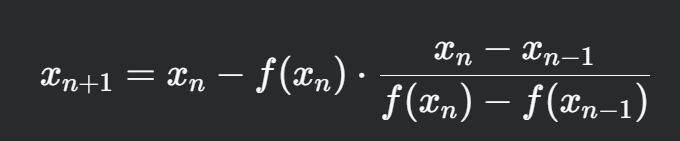

% % pid_count is counter for number of iterations till desired tracking is achieved
% pid_iter = 30;
% Kt_history = ones(pid_iter, 1);
% error_history = zeros(size(Kt_history));
% 
% %init stuctures for CL runs
% [model, input, trial, control] = CL_model_reset(w0,target, x_init, periods, dt);
% %do initial run
% control.Kd = Kt_history(1);
% [~, trial_out] = closedloop_test(model, input, trial, control);
% [~, x_lin] = get_last_n_periods(trial_out.t_span, trial_out.X(:, 1), 10);
% error_history(1) = max(x_lin)/target - 1;
% 
% Kt_history(2) = Kt_history(1)+0.1;
% 
% for pid_count = (2:pid_iter)
%     % run naive control model
%     control.Kd = Kt_history(pid_count);
%     [~, trial_out] = closedloop_test(model, input, trial, control);
%     [~, x_lin] = get_last_n_periods(trial_out.t_span, trial_out.X(:, 1), 10);
%     ss_amp = max(x_lin);
%     error_factor = ss_amp/target - 1 % percent error
% 
%     % check if within tolerance or if max iterations reached
%     tol_cond = abs(error_factor) < 0.01;
%     iter_cond = pid_count == pid_iter;
%     if(tol_cond)
%         "control within tolerance with Kd = " + control.Kd
%         break;
%     elseif(iter_cond)
%         "couldnt converge in " + pid_iter + " iterations"
%         break;
%     end
% 
%     % secant iteration
%     error_history(pid_count) = error_factor;
%     xn = Kt_history(pid_count-1:pid_count);
%     fx = error_history(pid_count-1:pid_count);
%     Kt_history(pid_count+1) = xn(2) - fx(2)*((xn(2)-xn(1))/(fx(2)-fx(1)));
% end